clear; clc; close all

ac = Aircraft();
ac.set_reference_point([0 0 0]);

%% Reference Definition
NOSE_REF_CG = [4.88;0.00;0.00];
tank_1_nose_ref = [4.00;0.00;0.00];
tank_2_nose_ref = [5.50;0.00;0.00];
engine_nose_ref = [6.00;0.00;0.00];
wing_ac_nose_ref = [4.20;0.00;0.00];
cg_to_tank_1 = tank_1_nose_ref - NOSE_REF_CG;
cg_to_tank_2 = tank_2_nose_ref - NOSE_REF_CG;
cg_to_engine = engine_nose_ref - NOSE_REF_CG;
cg_to_wing_ac = wing_ac_nose_ref - NOSE_REF_CG;

%% Mass Properties
ac.mass.set_mass_properties(9300,55800,63100,118000,0,0,0,[0 0 0]);
ac.mass.add_fuel_tank(cg_to_tank_1.',3000,'distributed');
ac.mass.add_fuel_tank(cg_to_tank_2.',1500,'distributed');
ac.mass.set_fuel_mass(2400);

%% Geometry
ac.geometry.wing_area = 27.87;
ac.geometry.wing_span = 9.14;
ac.geometry.mean_aerodynamic_chord = 3.45;
ac.geometry.ref_area = 27.87;
ac.geometry.ref_span = 9.14;
ac.geometry.ref_chord = 3.45;
ac.geometry.ref_point = cg_to_wing_ac.';

%% Aerodynamics
ac.set_aerodynamics(CoefficientAerodynamics(@F16Lookup));

%% Control Surfaces
cfg = ac.get_configurator();

cfg.add_control_surface('name','aileron','surface_type','aileron','classification','primary','axis',[1 0 0],'max_deflection',deg2rad(20),'min_deflection',deg2rad(-20),'dCl',0.05,'dCm',0,'dCn',0);
cfg.add_control_surface('name','elevator','surface_type','elevator','classification','primary','axis',[0 1 0],'max_deflection',deg2rad(25),'min_deflection',deg2rad(-25),'dCl',0,'dCm',-0.10,'dCn',0);
cfg.add_control_surface('name','rudder','surface_type','rudder','classification','primary','axis',[0 0 1],'max_deflection',deg2rad(30),'min_deflection',deg2rad(-30),'dCl',0,'dCm',0,'dCn',-0.08);

%% Propulsion
cfg.add_propulsive_element('name','F100_PW_229','element_type','turbofan_afterburning','max_output',128992,'position',cg_to_engine.','direction',[1 0 0],'fuel_rate',2.5,'thrust_model',@(thr,M,alt,V,rho) F100ThrustModel(thr,M,alt,V,rho,128992));

%% Control Vector
n_cs = numel(ac.control_surfaces);
n_pe = numel(ac.propulsive_elements);
n_total = n_cs + n_pe;

%% Trim Solver
solver = ac.get_trim_solver();
solver.use_fmincon = true;
solver.trim_tolerance = 1e-5;
solver.max_iterations = 500;

%% Mission Segments
fprintf('Full Mission Dynamics\n')

Full Mission Dynamics



empty_seg = struct('type','','h_start',0,'h_end',0,'mach',0,'mach_end',0,'gamma',0,'gamma_end',0,'altitude',0,'duration',0);
segments = repmat(empty_seg,1,3);

segments(1).type = 'climb_descent';
segments(1).h_start = 0;
segments(1).h_end = 9144;
segments(1).mach = 0.5;
segments(1).mach_end = 0.6;
segments(1).gamma = deg2rad(8);
segments(1).gamma_end = deg2rad(8);

segments(2).type = 'cruise';
segments(2).altitude = 9144;
segments(2).mach = 0.6;
segments(2).mach_end = 0.6;
segments(2).duration = 300;
segments(2).gamma = 0;
segments(2).gamma_end = 0;

segments(3).type = 'climb_descent';
segments(3).h_start = 9144;
segments(3).h_end = 0;
segments(3).mach = 0.5;
segments(3).mach_end = 0.3;
segments(3).gamma = deg2rad(-4);
segments(3).gamma_end = deg2rad(-4);

%% Mission Planner
mp = ac.get_mission_planner(0.5);
mp.build_mission(segments);
mp.compute_trim_schedule('dh_m',300,'max_iters',15000,'tol',1e-4);

[climb_descent] h=0m M=0.500 -> OK  alpha=1.99 deg  thr=0.350
[climb_descent] h=300m M=0.503 -> OK  alpha=2.07 deg  thr=0.356
[climb_descent] h=600m M=0.507 -> OK  alpha=2.16 deg  thr=0.363
[climb_descent] h=900m M=0.510 -> OK  alpha=2.24 deg  thr=0.369
[climb_descent] h=1200m M=0.513 -> OK  alpha=2.34 deg  thr=0.377
[climb_descent] h=1500m M=0.516 -> OK  alpha=2.43 deg  thr=0.384
[climb_descent] h=1800m M=0.520 -> OK  alpha=2.53 deg  thr=0.392
[climb_descent] h=2100m M=0.523 -> OK  alpha=2.63 deg  thr=0.400
[climb_descent] h=2400m M=0.526 -> OK  alpha=2.74 deg  thr=0.409
[climb_descent] h=2700m M=0.530 -> OK  alpha=2.85 deg  thr=0.419
[climb_descent] h=3000m M=0.533 -> OK  alpha=2.96 deg  thr=0.428
[climb_descent] h=3300m M=0.536 -> OK  alpha=3.08 deg  thr=0.436
[climb_descent] h=3600m M=0.539 -> OK  alpha=3.21 deg  thr=0.444
[climb_descent] h=3900m M=0.543 -> OK  alpha=3.33 deg  thr=0.452
[climb_descent] h=4200m M=0.546 -> OK  alpha=3.47 deg  thr=0.461
[climb_descent] h=4500m M=0.549


fprintf('Total duration   : %.1f s\n',mp.mission.total_duration)

Total duration   : 1706.5 s


fprintf('Mission points   : %d\n',numel(mp.mission.time_vector))

Mission points   : 3416


fprintf('Alt range        : %.0f - %.0f m\n',min(mp.mission.altitude_profile),max(mp.mission.altitude_profile))

Alt range        : 0 - 9144 m


fprintf('Trim convergence : %.1f%%\n',100*mean(mp.mission.converged_profile))

Trim convergence : 100.0%



%% Reference Summary
ref_point = ac.get_reference_point();
cg_current = ac.mass.get_cg();
ref_point = ref_point(:);
cg_current = cg_current(:);
cg_shift = cg_current - ref_point;
fprintf('Reference point  : [%.3f %.3f %.3f] m\n',ref_point(1),ref_point(2),ref_point(3))

Reference point  : [0.000 0.000 0.000] m


fprintf('Current CG       : [%.3f %.3f %.3f] m\n',cg_current(1),cg_current(2),cg_current(3))

Current CG       : [-0.181 0.000 0.000] m


fprintf('CG-ref shift     : [%.3f %.3f %.3f] m\n',cg_shift(1),cg_shift(2),cg_shift(3))

CG-ref shift     : [-0.181 0.000 0.000] m


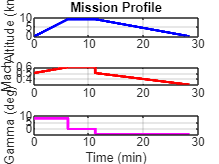


mp.plot_mission();